# Ejemplo de función de transferencia

Función de transferencia con ceros en 1 y 3, y con polos en 0 y 4

syms s
num = (s-1)*(s-3)

$$num = \left(s-1\right)\,\left(s-3\right)$$

den = (s)*(s-4)

$$den = s\,\left(s-4\right)$$


transfer = num/den

$$transfer = \frac{\left(s-1\right)\,\left(s-3\right)}{s\,\left(s-4\right)}$$

Expresada como polinomios

transfer = expand(num)/expand(den)

$$transfer = -\frac{s^{2}-4\,s+3}{4\,s-s^{2}}$$

Graficando la relación de esta función de transferencia en magnitud

num = [1, -4, 3]

num =      1    -4     3


den = [1, -4, 0]

den =      1    -4     0


H = tf(num, den)

H =
 
  s^2 - 4 s + 3
  -------------
    s^2 - 4 s
 
Continuous-time transfer function.



% bode(H)

Aproximación asintotica 1

%asymp(H)

Aproximación asintotica 2

ii =      1
     2
     3


jj =      1
     1
     1


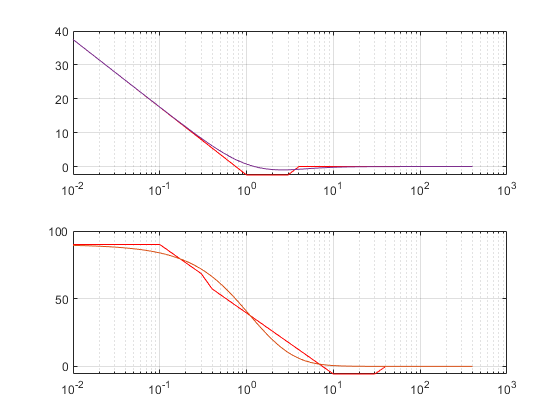

bode_asymptotic(num, den)